# Performance of Different Loop Orderings

This Live Script helps you compare and contrast the performance of varous implementations of matrix-matrix multiplication.  In particular, simple implementations of the six different orderings of the three loops are compared.

Clear all variables.

clear

On the terminal command line, type 'make test_IJP' which will compile and time the implementation in Gemm_IJP.c.  When completed, this creates output file 'output_IJP' with timing data.  This Life Script then creates graphs from that timing data.

## Load timing data

output_IJP
data_IJP = data;
version_IJP = your_version;

## Make sure you are getting the right answer

In the output file, for each execution of your implementation, timing data is collected as well as how close the answer is to the answer attained by the reference implementation.  Here we look at the maximum difference over all experiments.  This should be somewhere on the order of 1e-11  or smaller.  Notice that you can expect some difference between the two implementations, due to round-off error and the order in which computations are performed.

MaxAbsDiff = max( abs( data_IJP( :, 6 ) ) )

MaxAbsDiff = 9.6634e-13

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine


## Plot execution time.

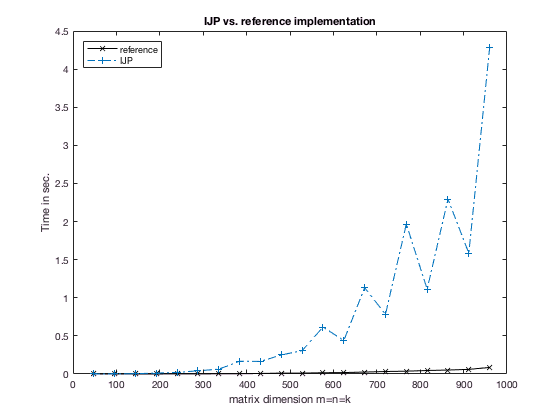

% Plot the reference implementation
plot( data_IJP( :, 1 ), data_IJP( :, 2 ), 'k-x' );   

hold all
 % Plot the performance data for Gemm_IJP
plot( data_IJP( :, 1 ), data_IJP( :, 4 ), '-.+' ); 

title( 'IJP vs. reference implementation' );
xlabel( 'matrix dimension m=n=k' );
ylabel( 'Time in sec.' );
legend( 'reference', ...
         version_IJP, ...
        'Location', 'NorthWest' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

## Plot performance in GFLOPS

We often view the rate at which routines compute rather than the time required for completing the computation.

When all matrices are $n \times n$, we know that a matrix-matrix  multiplication$ A B + C$ requires $2n^3$ floating point operations (flops).  This means that the number of operations performed per second is given by ${2 n^3}/{t}$ flops, where $t$ is the time, in seconds, for computing the multiplication.  Now, a typical current core can perform billions of flops per second, so instead we report performance in GFLOPS/sec. (billions of flops per second): ${2 n^3}/{t} \times 10^{-9}$.  This performance data is already computed in the fourth column of array "data_Gemm".

In the plot, we compare against a high-performance implementation of the dgemm BLAS routine for computing matrix-matrix multiplication.

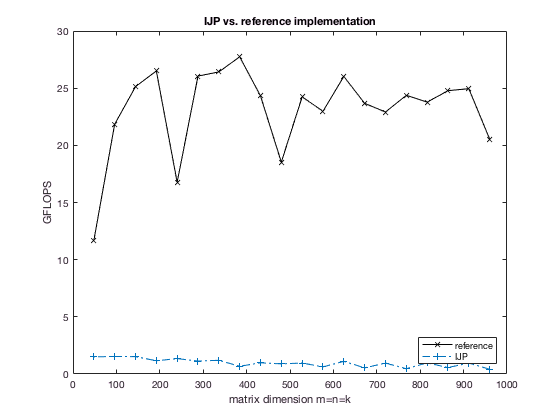

figure

% Plot the reference implementation
plot( data_IJP( :, 1 ), data_IJP( :, 3 ), 'k-x' );   

hold all
 % Plot the performance data for Gemm_IJP
plot( data_IJP( :, 1 ), data_IJP( :, 5 ), '-.+' ); 

title( 'IJP vs. reference implementation' );
xlabel( 'matrix dimension m=n=k' );
ylabel( 'GFLOPS' );
legend( 'reference', ...
         version_IJP, ...
        'Location', 'SouthEast' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

## Compare all 6 loop orderings

After implementing all the 6 loop orderings, on the terminal command line, type 

    make test_IJP

    make test_IPJ

    make test_JIP

    make test_JPI

    make test_PIJ

    make test_PJI

which will compile and time the various implementations.  When completed, this creates output files with timing data.  

## Load timing data

output_IJP
data_IJP = data;
version_IJP = your_version;

output_IPJ
data_IPJ = data;
version_IPJ = your_version;

output_JIP
data_JIP = data;
version_JIP = your_version;

output_JPI
data_JPI = data;
version_JPI = your_version;

output_PIJ
data_PIJ = data;
version_PIJ = your_version;

output_PJI
data_PJI = data;
version_PJI = your_version;

## Make sure you are getting the right answer

In the output file, for each execution of your implementation, timing data is collected as well as how close the answer is to the answer attained by the reference implementation.  Here we look at the maximum difference over all experiments.  This should be somewhere on the order of 1e-11  or smaller.  Notice that you can expect some difference between the two implementations, due to round-off error and the order in which computations are performed.

MaxAbsDiff = max( abs( data_IJP( :, 6 ) ) )

MaxAbsDiff = 9.6634e-13

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine



MaxAbsDiff = max( abs( data_IPJ( :, 6 ) ) )

MaxAbsDiff = 9.6634e-13

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine



MaxAbsDiff = max( abs( data_JIP( :, 6 ) ) )

MaxAbsDiff = 9.6634e-13

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine



MaxAbsDiff = max( abs( data_JPI( :, 6 ) ) )

MaxAbsDiff = 9.6634e-13

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine



MaxAbsDiff = max( abs( data_PIJ( :, 6 ) ) )

MaxAbsDiff = 9.6634e-13

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine



MaxAbsDiff = max( abs( data_PIJ( :, 6 ) ) )

MaxAbsDiff = 9.6634e-13

if ( MaxAbsDiff > 1.0e-10 )
    disp( 'Hmmm, better check if there is an accuracy problem' );
else
    disp( 'It appears all is fine' );
end

It appears all is fine


## Plot execution time.

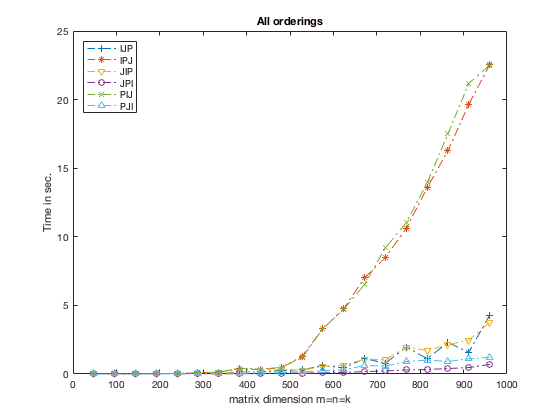

figure

% Plot the performance data for the different implementations
plot( data_IJP( :, 1 ), data_IJP( :, 4 ), '-.+' ); 

hold all

plot( data_IPJ( :, 1 ), data_IPJ( :, 4 ), '-.*' );
plot( data_JIP( :, 1 ), data_JIP( :, 4 ), '-.v' );
plot( data_JPI( :, 1 ), data_JPI( :, 4 ), '-.o' );
plot( data_PIJ( :, 1 ), data_PIJ( :, 4 ), '-.x' );
plot( data_PJI( :, 1 ), data_PJI( :, 4 ), '-.^' );

title( 'All orderings' );
xlabel( 'matrix dimension m=n=k' );
ylabel( 'Time in sec.' );
legend(  version_IJP, ...
         version_IPJ, ...
         version_JIP, ...
         version_JPI, ...
         version_PIJ, ...
         version_PJI, ...
        'Location', 'NorthWest' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

## Plot performance in GFLOPS

We often view the rate at which routines compute rather than the time required for completing the computation.

When all matrices are $n \times n$, we know that a matrix-matrix  multiplication$ A B + C$ requires $2n^3$ floating point operations (flops).  This means that the number of operations performed per second is given by ${2 n^3}/{t}$ flops, where $t$ is the time, in seconds, for computing the multiplication.  Now, a typical current core can perform billions of flops per second, so instead we report performance in GFLOPS/sec. (billions of flops per second): ${2 n^3}/{t} \times 10^{-9}$.  This performance data is already computed in the fifth column of array "data".

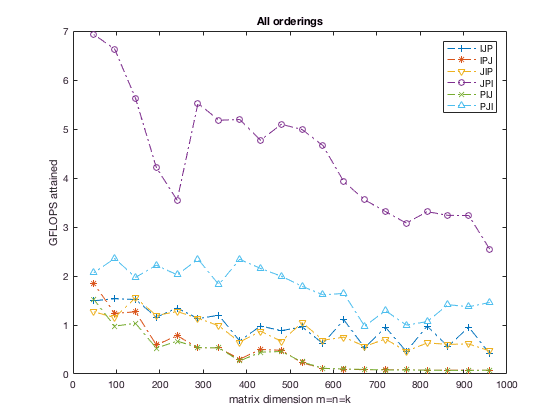

figure

% Plot the performance data for the different implementations
plot( data_IJP( :, 1 ), data_IJP( :, 5 ), '-.+' ); 

hold all

plot( data_IPJ( :, 1 ), data_IPJ( :, 5 ), '-.*' );
plot( data_JIP( :, 1 ), data_JIP( :, 5 ), '-.v' );
plot( data_JPI( :, 1 ), data_JPI( :, 5 ), '-.o' );
plot( data_PIJ( :, 1 ), data_PIJ( :, 5 ), '-.x' );
plot( data_PJI( :, 1 ), data_PJI( :, 5 ), '-.^' );

title( 'All orderings' );
xlabel( 'matrix dimension m=n=k' );
ylabel( 'GFLOPS attained' );
legend(  version_IJP, ...
         version_IPJ, ...
         version_JIP, ...
         version_JPI, ...
         version_PIJ, ...
         version_PJI, ...
        'Location', 'NorthEast' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero

## Comparison with high-performance implementation

While the last graph makes it seem like impressive performance improvements can be made by picking the right loop ordering, it is when one compares against a high-performance "reference" implementation that one realizes there is a lot of room for improvement:

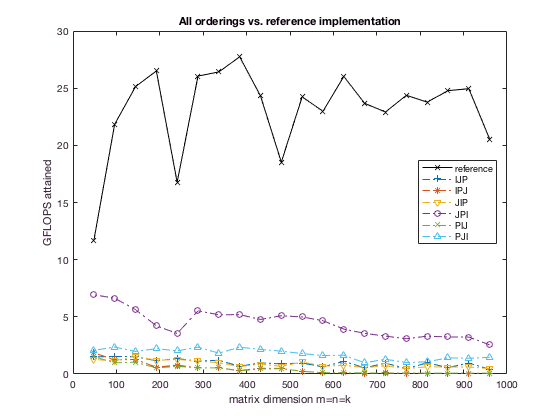

figure

% Plot the reference implementation
plot( data_IJP( :, 1 ), data_IJP( :, 3 ), 'k-x' );   

hold all

% Plot the performance data for the different implementations
plot( data_IJP( :, 1 ), data_IJP( :, 5 ), '-.+' ); 
plot( data_IPJ( :, 1 ), data_IPJ( :, 5 ), '-.*' );
plot( data_JIP( :, 1 ), data_JIP( :, 5 ), '-.v' );
plot( data_JPI( :, 1 ), data_JPI( :, 5 ), '-.o' );
plot( data_PIJ( :, 1 ), data_PIJ( :, 5 ), '-.x' );
plot( data_PJI( :, 1 ), data_PJI( :, 5 ), '-.^' );

title( 'All orderings vs. reference implementation' );
xlabel( 'matrix dimension m=n=k' );
ylabel( 'GFLOPS attained' );
legend(  'reference', ...
         version_IJP, ...
         version_IPJ, ...
         version_JIP, ...
         version_JPI, ...
         version_PIJ, ...
         version_PJI, ...
        'Location', 'East' );
    
% Adjust the x axis
v = axis;     % extract the current ranges
axis( [ 0 v(2) 0 v(4) ] )  % start the x axis and y axis at zero